# ViconExtract main

run to open gui with vesettings

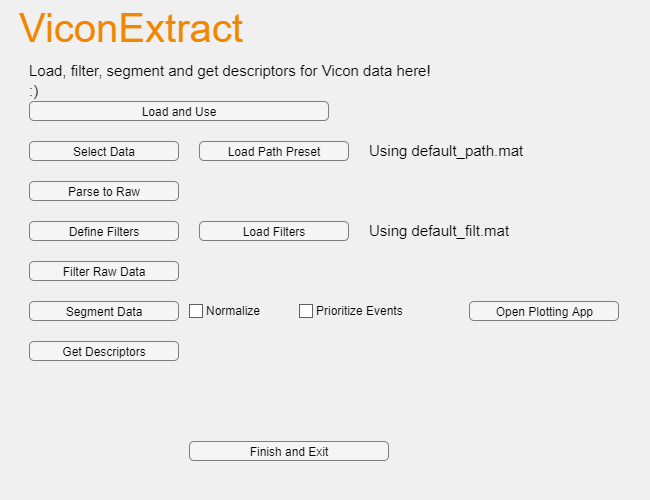

addpath(genpath(pwd));  % PWD maximum depth is ...\viconExtract to run
vesettings = importsettings();
ve_gui = ViconExtract_gui();

Runtime settings

function vesettings = importsettings()
    vesettings = struct('dontuse', 'dontuse');

% GENERAL SETTINGS SECTION
    % Fields which indicate Vicon data
    vesettings.Viconfields = {'ForcePlate', 'Markers', 'JointAngle', 'JointVelocity', 'JointMoment', 'JointForce', 'JointPower', 'SubjectDetails'};
    
    % Vicon Data that is side independent
    vesettings.side_indep = ["Events", "Markers"];

    % Vicon Data that can is normalized
    vesettings.can_norm = ["JointMoment", "JointForce", "JointPower"];

    % Vicon Data with XYZ components
    vesettings.xyz_list = ["Force", "Moment", "CoP", "Angle", "Velocity", "Power"];

    % Vicon frequency
    vesettings.vicon_freq = 100; % Hz

    % segment_strides Interpolation Number
    vesettings.n_interp = 100;

    % segmentation z-score threshold for stride outlier removal
    vesettings.zscoremax = 3;   % default is 3

    % Eventsegment alignment search radius
    vesettings.align_search_rad = 10; % default is 10


% OVERRIDES SECTION ~~~ Altering settings could change behavior significantly

    % import_overrideallows importing and using of unknown/invalid .mat files
    vesettings.import_override = false;     % default is false

    % forceplatez_override forces program to use existing forceplate_force_z for segmentation
    % override may cause unintended/faulty behavior from GRFSegment_plus
    vesettings.forceplatez_override = true;    % default is true
    
    vesettings = rmfield(vesettings, 'dontuse');
end